Load the data file

load('2User2AntennaBS.mat');

%% Making vectors.
y1 = real(y1);
y2 = real(y2);

%% Account for any delay.
d1 = finddelay(x1, y1)

d1 = 20

d2 = finddelay(x2, y2)

d2 = 20

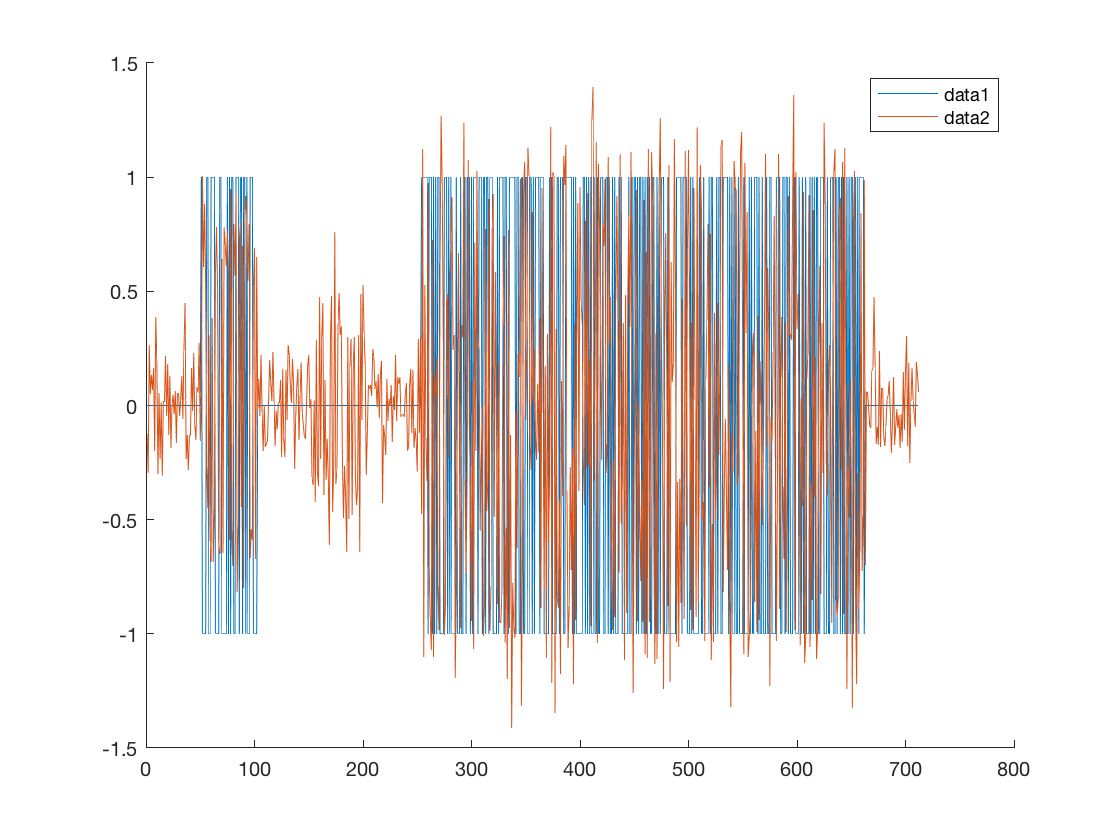


cla
hold on
plot(x1(1:100:71200))
plot(y1(1:100:71200))
hold off

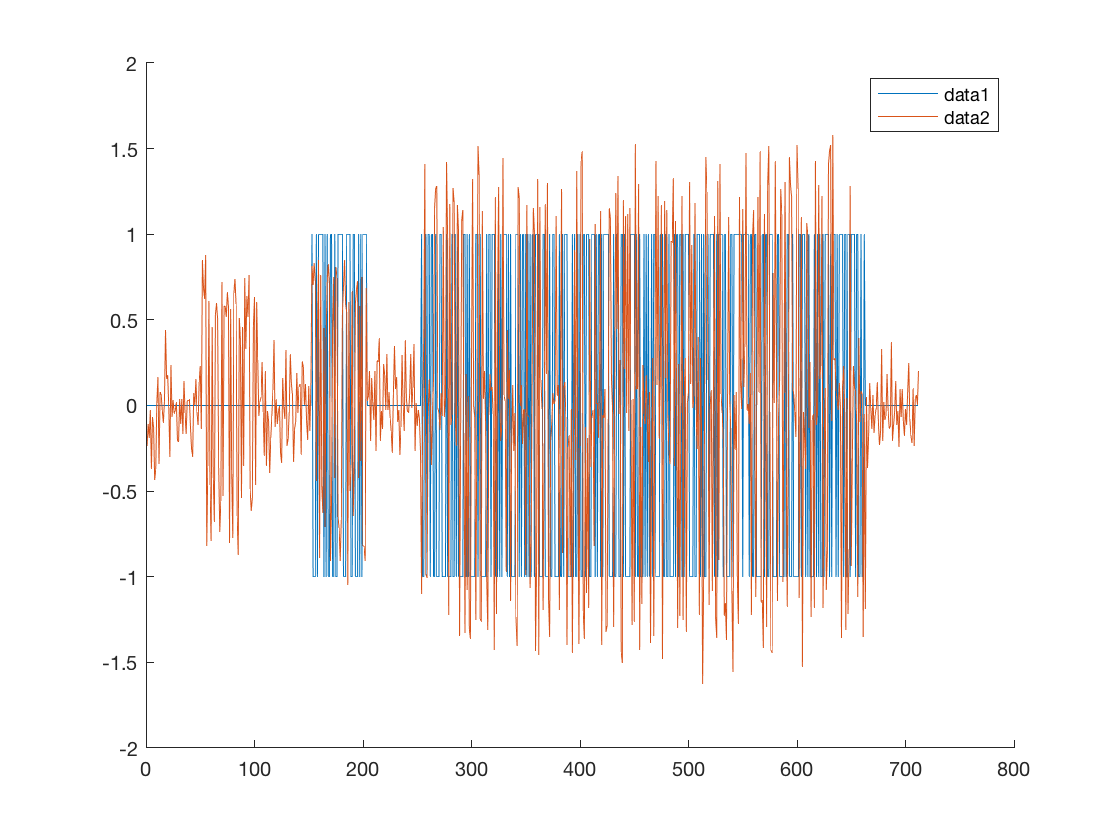


figure
hold on
plot(x2(1:100:71200))
plot(y2(1:100:71200))
legend
hold off

y1 = y1(d1:end);
y2 = y2(d2:end);

% Transmitter 1 transmitting parameters
t1_start = 5001; 
t1_end = pulseWidth * 128 + t1_start - 1;
t1_end - t1_start

ans = 5119


% Transmitter samples
x1_t1 = x1(t1_start : t1_end);

% receivers
y1_t1 = y1(t1_start : t1_end);
y2_t1 = y2(t1_start : t1_end);

% transmitter 2 transmits
t2_start = t1_end + 5001;
t2_end = t2_start + (pulseWidth * 128) - 1;

x2_t2 = x2(t2_start : t2_end);

% receivers
y1_t2 = y1(t2_start : t2_end);
y2_t2 = y2(t2_start : t2_end);

Get the system response H by 

% calculating the channel response
% when y1 is listening to x1 speak
h11 = mean(y1_t1 ./ x1_t1)

h11 = -0.6280


% when y2 is listening to x1 speak
h21 = mean(y2_t1 ./ x1_t1)

h21 = -0.5917

% when y1 is listening to x2 speak
h12_raw = y1_t2 ./ x2_t2

h12_raw =     0.0063
    0.3701
    0.3188
    0.2634
    0.2355
    0.6291
    0.3686
    0.2549
    0.4518
    0.1694


h12 = mean(y1_t2 ./ x2_t2)

h12 = 0.3552


% when y2 is listening to x2 speak
h22 = mean(y2_t2 ./ x2_t2)

h22 = -0.6404


%% Creating the channel response matrix.
H = [h11 h12; h21 h22];

%% Calculating the weight vectors.

asdasd

%% Calculate the weight vectors.
% we know that H* x w = [1; 0] for x1
w1 = inv(H') * [1; 0]

w1 =    -1.0459
   -0.5801



% we know that H* x w = [0; 1] for x2
w2 = inv(H') * [0; 1]

w2 =     0.9662
   -1.0255


## Apply the weight vectors.

x = [x1'; x2'];
y = [y1'; y2'];

x1_hat = w1' * y;
x2_hat = w2' * y;

Ensure that the fit works for when the channel is silent

guess_start = 60000;
% 66000
guess_end = guess_start + 1000;

% guess_start = 25241;

guess_x = sign(round(x1_hat));

guesses = guess_x(guess_start:guess_end)

guesses =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     0     1     1     1     1     1     1     1     1


actuals = x1(guess_start:guess_end)

actuals =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1



cla
hold on
stem(actuals)
stem(guesses)
legend
errors = abs(reshape(actuals' - guesses, 1, []))

errors =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0


% stem(num_errors)
legend("Original", "Recoded", "Errors")

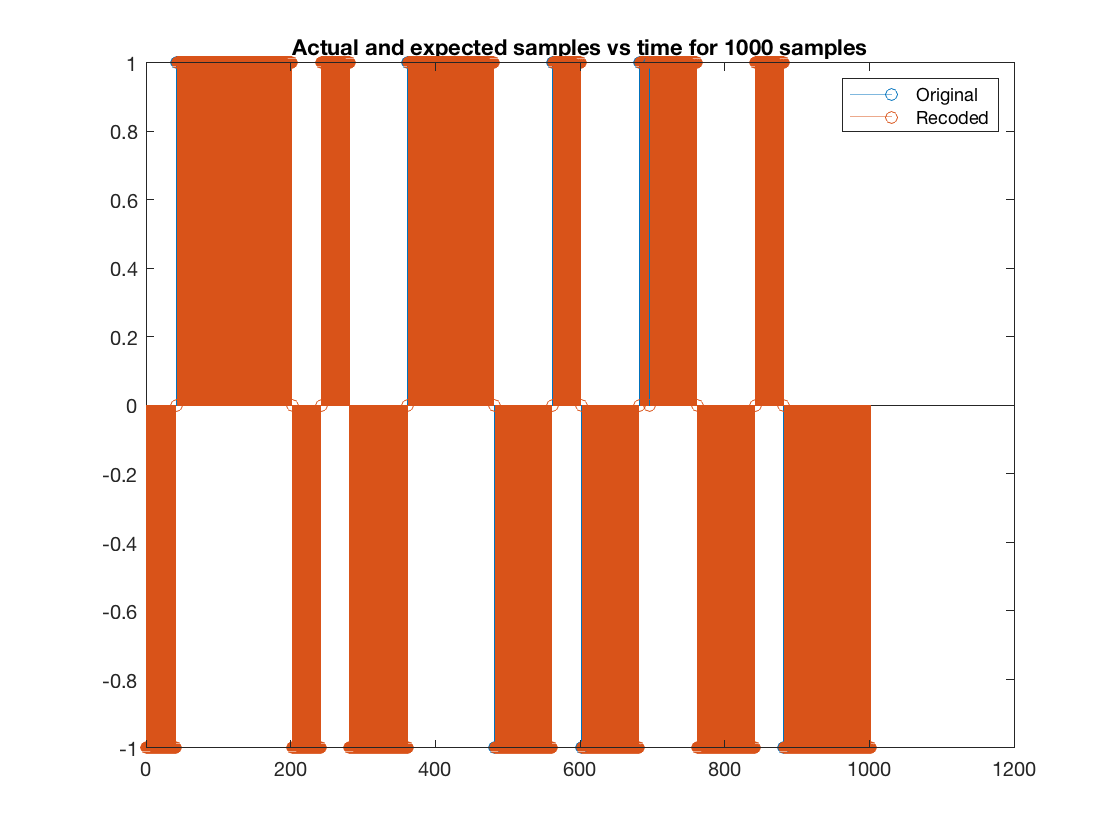

title("Actual and expected samples vs time for 1000 samples")
saveas(gca, "actualvsexpected.svg")

Now,  make sure the fit continues to work when both channels are noisy

sign(0.0000)

ans = 0

% actuals = guess_x(guess_start :guess_end )
% hold on

% stem( )
% stem(x1(guess_start :guess_end ))
% hold off


% %% Calculate the error.
% % look at the last 1024 data bits to calculate the error
% intermediate_data_length = 128 * pulseWidth;
% starting3 = 5000 + intermediate_data_length + 5000 + intermediate_data_length + 5000 + 1;
% last_message_length = 1024*40;
% 
% % crop off the end of the data
% x_check = x(:, starting3 : starting3 + last_message_length);
% y_check = sign(y(:, starting3 : starting3 + last_message_length));
% 
% % sample in the middle of the pulse width
% x_check = x_check(:, 20 : pulseWidth : end);
% y_check = y_check(:, 20 : pulseWidth : end);
% 
% figure
% hold on
% stem(x_check(1,:));
% stem(y_check(1,:));
% 
% 
% figure
% hold on
% stem(x_check(2,:));
% stem(y_check(2,:));
% 
% equality1 = (y_check(1,:) ~= x_check(1,:));
% equality2 = (y_check(2,:) ~= x_check(2,:));
% error_rate1 = sum(equality1)/length(x_check)
% error_rate2 = sum(equality2)/length(x_check)